x = [0,1,2];
y = [1,0,1];
path = Path(x,y,0.25);

ax = 0

bx = 0.3536

cx = 0.8232

ay = 0.3536

by = -0.3536

cy = 0.1768

len = path.getLength()

len = 2.7342

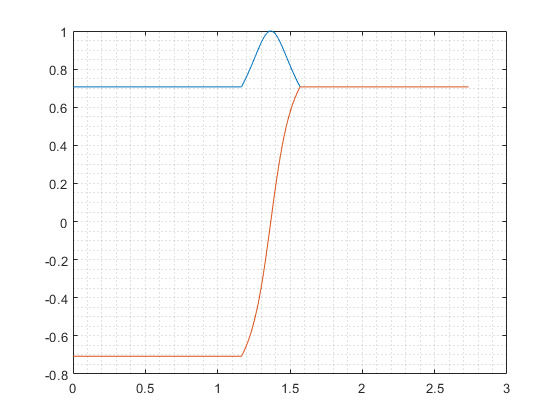

s = [0:.001:len];
[x1,y1] = path.diff(s);
[x2,y2] = path.diff(s,2);
figure();
plot(s,x1);
hold on
plot(s,y1);
grid minor

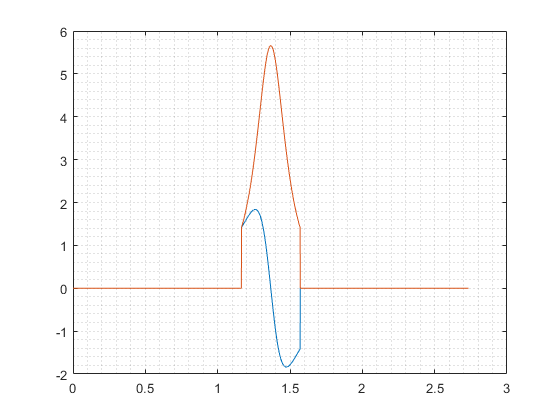


figure()
plot(s,x2);
hold on;
grid minor;
plot(s,y2);

[xt,yt] = path.diff(s)

xt =     0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071
    0.7071


yt =    -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071
   -0.7071


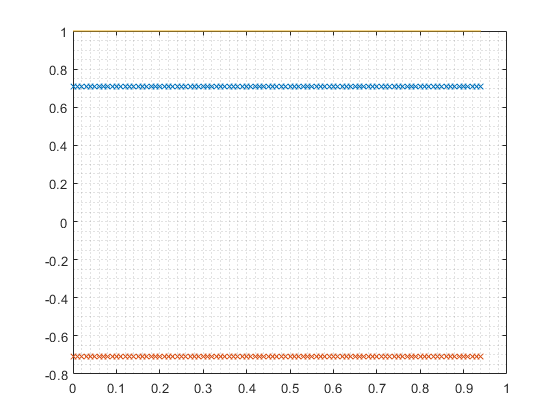


figure();
plot(s,xt,":x");
hold on
plot(s,yt,":x")
plot(s,sqrt(xt.^2+yt.^2))
grid minor

b = QuadraticBezierCurve([0,1,2], [0,0,1], 0.5);

ax = -0.1464

bx = 1

cx = 0.5000

ay = 0.3536

by = -1.2246e-16

cy = 6.1232e-17

dt = 0.01

dt = 0.0100

s = [0:0.01:b.length]

s =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


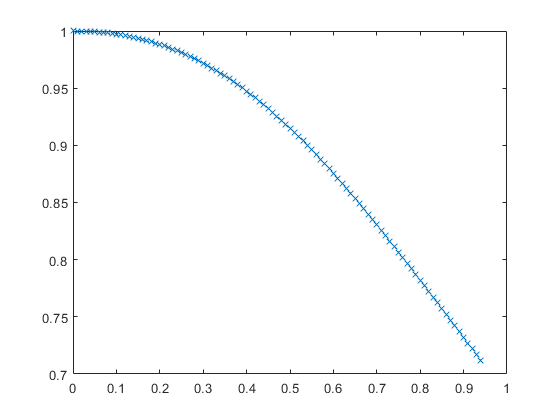

[xs,ys] = b.diff(s);
[xss,yss] = b.diff(s,2);
figure();
plot(s,xs,":x")
hold on

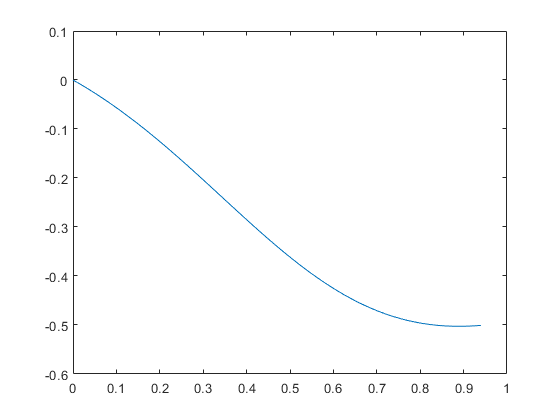

figure();

plot(s, xss)

ax = (b.startPoint.x - 2*b.controlPoint.x + b.endPoint.x);
ay = (b.startPoint.y - 2*b.controlPoint.y + b.endPoint.y);
bx = (2*b.controlPoint.x - 2*b.startPoint.x);
by = (2*b.controlPoint.y - 2*b.startPoint.y);

sIn = @(t)( (t/2 + (4*ax*bx + 4*ay*by)/(4*(4*ax^2 + 4*ay^2)))*(t*(4*ax*bx + 4*ay*by) ...
    + bx^2 + by^2 + t^2*(4*ax^2 + 4*ay^2))^(1/2) ...
   - (log((2*ax*bx + 2*ay*by + t*(4*ax^2 + 4*ay^2))/(4*ax^2 + 4*ay^2)^(1/2) ...
   + (t*(4*ax*bx + 4*ay*by) + bx^2 + by^2 ...
   + t^2*(4*ax^2 + 4*ay^2))^(1/2))*((4*ax*bx + 4*ay*by)^2/4 ...
   - (4*ax^2 + 4*ay^2)*(bx^2 + by^2)))/(2*(4*ax^2 + 4*ay^2)^(3/2)));

s = @(t) (sIn(t)-sIn(0))
ds = @(t) ((4*ax^2*t^2 + 4*ax*bx*t + 4*ay^2*t^2 + 4*ay*by*t + bx^2 + by^2)^(1/2));
s0 = [0:0.01:b.length];
t = zeros(1,length(s0));
for i=1:length(s0)
        t_prev = 2;
        while abs(t(i)-t_prev) > 1e-4
            t_prev = t(i);
            t(i) = t(i) - (s(t(i)) - s0(i)) / ds(t(i));
        end
end

figure();
plot(t(2:length(t)),diff(t)./diff(s0))
hold on
plot(t(2:length(t)),diff(s0)./diff(t))
%plot(s0,t)
